#   ECSE 343: Numerical Methods in Engineering

#  Assignment 4

Due Date: 9th April 2021

**Student Name: Theodore Janson**

**Student ID:    260868223**

Please type your answers and write you code in this .mlx script. If you choose to provide the handwritten answers, please scan your answers and include those in SINGLE pdf file.

Please submit this **.mlx** file along with the **PDF** copy of this file.

Note: You can write the function in the appendix section using the provided stencils.

Question 1: **Nonlinear Equations for univariate case.**

a) Bisection Method is used for tfinding the roots of a continuous function, $f\left(x\right)$, given endpoints;$a,b$ with $f\left(a\right)\ldotp f\left(b\right)<0$ . The interval $\left\lbrack a\;\;b\right\rbrack$contains a root, $x_r$, because $f\left(a\right)$ and $f\left(b\right)$ have opposite signs.

Bisection method bisects the given interval at the midpoint, $c=\frac{a+b}{2}$ and then chooses a new interval based such that end of point of interval have opposite signs, i.e., if $f\left(a\right)\ldotp f\left(c\right)<0$, then the new interval is set to $\left\lbrack a\;\;c\right\rbrack$, else if $f\left(c\right)\ldotp f\left(b\right)<0$ then the interval is set to $\left\lbrack c\;\;b\right\rbrack$.

The above procedure is repeated until the following two conditions are simultaneously met, 

- The function value at the interval is sufficiently small, i.e., ${\left\|f\left(c\right)\right\|}_2 <\epsilon_{\textrm{tolerance}}$

- The new interval is sufficiently small, i.e., ${\left\|a-b\right\|}_2 <\epsilon_{\textrm{tolerance}}$

Implement the Bisection Method in the cell below to find the root of $f\left(x\right)=x^4 -{\textrm{􀀀2}\;x}^2 -4$ in the interval $\left\lbrack -3\;\;\;3\right\rbrack \;$using $\epsilon_{\textrm{tolerance}} ={10}^{-5}$. **Show the number of iterations the bisection method took to converge.**

Use the cell below to implement your code. 

Note: There is no need to write the function for Bisection Method. However, if you wish to implement the function, use the appendix.

F = [1 0 -2 0 -4]; %polynomial coefficients
eps = 10^-5;

%interval bounds
a = -3; 
b = 3;

iterations = 0;

while true
    c = (a + b) / 2;        %evaluate midpoint
    Fc = polyval(F, c);     %evaluate polynomial at midpoint and interval bounds
    Fa = polyval(F, a);
    Fb = polyval(F, b);

    if Fa*Fc < 0            %if sign change occurs on lower half, restrict interval to that half
        b = c;
        root = (a+b)/2;
    elseif Fb*Fc < 0        %likewise for upperhalf
        a = c;
        root = (a+b)/2;
    elseif Fc == 0          
        disp('Exact solution')
        root = c;
        break
    end

    root_convergence = norm(Fc, 'fro');        %convergence of root estimate
    interval_convergence = norm(a-b, 'fro');   %convergence of interval
    
    if root_convergence < eps && interval_convergence < eps
        break
    end
    iterations = iterations +1;
end

disp('Bisection Method result for root of Polynomial on interval ')

Bisection Method result for root of Polynomial on interval 


root

root = -1.7989

root_convergence

root_convergence = 1.2621e-06

iterations

iterations = 22

b) ** Newton-Raphson**

 Bisection Method requires the given function,$f\left(x\right)$ to be continuous, Newton-Raphson requires $f\left(x\right)$ to be continuous and differentiable. While the Newton- Raphson method converges faster than the bisection method, however, Newton-Raphson method does not guarantee convergence. Newton-Raphson works by linearising the $f\left(x\right)$, at the given initial guess, $x^{\left(0\right)}$as shown below


$$f\left(x\right)=f\left(x^{\left(0\right)} \right)+{f\left(x^{\left(0\right)} \right)}^{\prime } \left(x-x^{\left(0\right)} \right)$$


Setting the expression on the right to zero, provides an approximation to the root, and we obtain


$$x^{\left(1\right)} =x^{\left(0\right)} -\frac{f\left(x^{\left(0\right)} \right)}{{f\left(x^{\left(0\right)} \right)}^{\prime } }$$


Then, the function,$\;f\left(x\right)$, is again linearised using approximation,$x^{\left(1\right)}$as the initial guess, to obtain new approximation of the root. After $k$ iterations the new approximation for the root becomes,

  
$$x^{\left(k+1\right)} =x^{\left(k\right)} -\frac{f\left(x^{\left(k\right)} \right)}{{f\left(x^{\left(k\right)} \right)}^{\prime } }$$


The above procedure is repeated untill the following two convergence condtions are simultaneously met,  

- The function value at new guess point is sufficiently small, i.e., ${\left\|f\left(x^{\left(k+1\right)} \right)\right\|}_2 <\epsilon_{\textrm{tolerance}}$

- The difference between the two consecutive solutions is sufficiently small, i.e., ${\left\|x^{\left(k+1\right)} -x^{\left(k\right)} \right\|}_2 <\epsilon_{\textrm{tolerance}}$

Implement the **Newton-Raphson** Method in the cell below to find the root of $f\left(x\right)=x^4 -{\textrm{􀀀2}\;x}^2 -4$ use intial guess of $x^{\left(0\right)} =3$ using $\epsilon_{\textrm{tolerance}} ={10}^{-5}$.  If the convergence is not reached in 100 iterations, quit the algorithm by displaying an error message indicating that Newton-Raphson failed to converge. 

Show the number of iterations the Newton-Raphson method took to converge. 

Also plot the 2-Norm of difference between consecutive solutions ${\left\|x^{\left(k+1\right)} -x^{\left(k\right)} \right\|}_2$ for each iteration. 

clear all;

norms_nm = [];
iterations = 0;

eps = 10^-5;

norms = [];
iterations = 0;

F = [1 0 -2 0 -4]; %polynomial
dF = [4 0 -4 0];   %polynomial derivative
x0 = 3;

while true
    %evaluate function and its derivative at x0
    Fx0 = polyval(F, x0);
    dFx0 = polyval(dF, x0);
    
    
    %Newtons method
    x = x0 - Fx0 / dFx0;
    
    %check convergence
    root_convergence = norm(x-x0, 'fro');
    norms(iterations+1) = root_convergence;
    
    x0 = x;
    
    if Fx0 == 0
        disp('Exact solution!')
        break
    end
    
    if dFx0 == 0
        %when derivative is 0, Newton's method fails
        disp('Line tangent at x0 does not intersect x-axis. Approximation not possible')
        break
    end
    
    iterations = iterations + 1;
    
    %Check convergence
    if root_convergence < eps || iterations > 100
        if iterations > 100
            disp('Failed to converge..')
        end
        break
    end
    
end

disp("Newton's Method result for root of polynomial")

Newton's Method result for root of artan(x)



root = x0

root = 1.7989

root_convergence

root_convergence = 1.9669e-06

iterations

iterations = 6

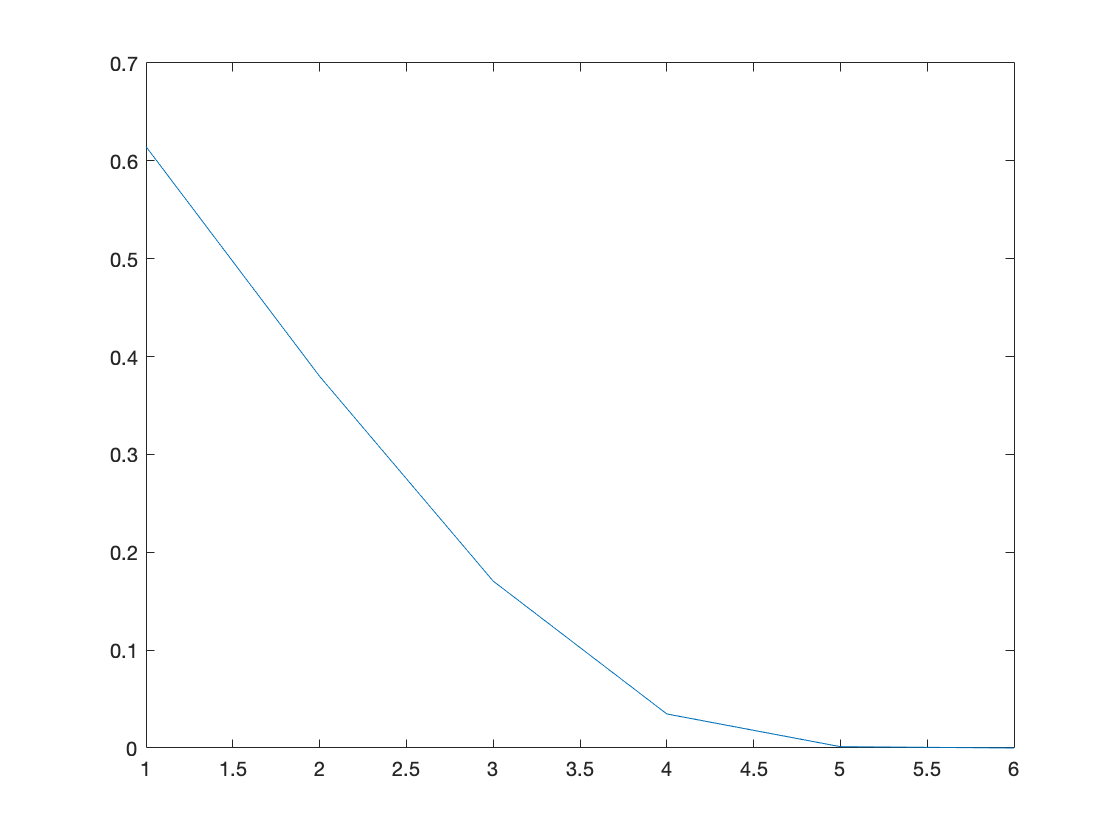


figure
hold on
plot(norms)
xlabel('Iterations')
ylabel('Norm')
title('Newtons Method on Polynomial)')
grid on

c) In this part implement the **Bisection Method**, and the** Newton-Raphson Method** to find the roots of $f\left(x\right)\;=\;\arctan \left(x\right)$. Use  $\epsilon_{\textrm{tolerance}} ={10}^{-5}$, to stop the algorithms. For bisection method use the interval $\left\lbrack -4\;\;4\;\right\rbrack$.  For Newton-Rapshon use $x^{\left(0\right)} =4$ as initial guess.  Comment on your findings.

Note: The derivative of $f\left(x\right)\;=\;\arctan \left(x\right)$ is $\;\frac{1}{x^2 +1}$

If the convergence is not reached for Newto-Raphson in 100 iterations, quit the function by displaying an error message indicating that Newton-Raphson failed to converge. Plot the 2-Norm of difference between consecutive solutions ${\left\|x^{\left(k+1\right)} -x^{\left(k\right)} \right\|}_2$ for each iteration, what can you conclude from the plot?

Use the cells below to implement both methods.

clear all;

eps = 10^-5;

%interval bounds
a = -4; 
b = 4;

iterations = 0;
norms_bs = [];

while true
    c = (a + b) / 2;        %evaluate midpoint
    Fc = atan(c);           %evaluate arctan at midpoint and interval bounds
    Fa = atan(a);
    Fb = atan(b);
    
    root_convergence = norm(Fc, 'fro');     %convergence of root estimate
    interval_convergence = norm(a-b, 'fro');   %convergence of interval
    iterations = iterations +1;
    norms_bs(iterations) = interval_convergence;

    
    if Fa*Fc < 0            %if sign change occurs on lower half, restrict interval to that half
        b = c;
        root = (a+b)/2;
    elseif Fb*Fc < 0        %likewise for upperhalf
        a = c;
        root = (a+b)/2;
    elseif Fc == 0          %exact solution
        root = c;
        break
    end

    %check convergence to 0
    if root_convergence < eps && interval_convergence < eps 
        break
    end
    
    
end

disp('Bisection Method result for root of Arctan(x) on interval ')

Bisection Method result for root of Arctan(x) on interval 


root

root = 0

root_convergence

root_convergence = 0

iterations

iterations = 1

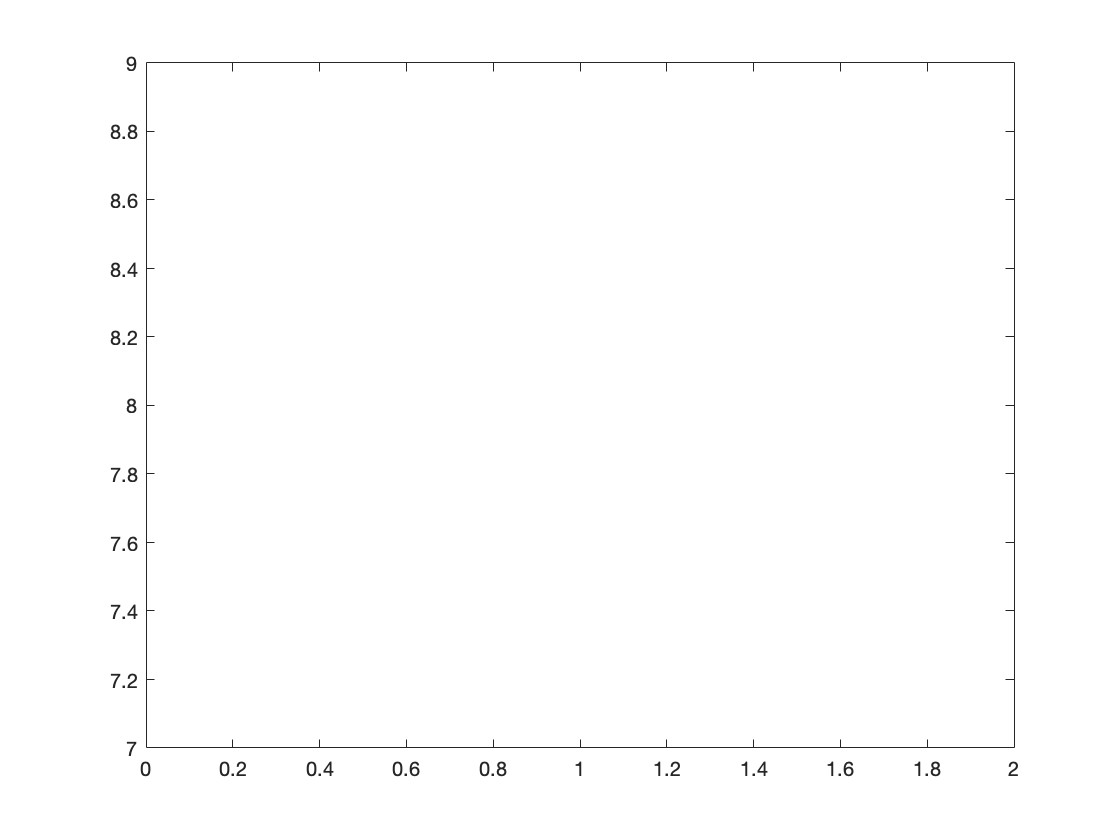


figure
hold on
plot(norms_bs)
xlabel('Iterations')
ylabel('Norm')
title('Bisection Method on Arctan(x) using -4,4')
grid on

The algorithm converged to an exact solution in 1 iteration. When the interval bounds were selected as -4 and 4, the midpoint evaluated at arctan(x) is arctan(0) = 0. 

 -----------------------------------------------------------------------------------------------------------------

clear all;

norms_nm = [];
iterations = 0;

eps = 10^-5;
x0 = 4.0;

dF = @(x) 1/(x^2+1);

while true
    %evaluate function and its derivative at x0
    Fx0 = atan(x0);
    dFx0 = dF(x0);
    
    %Newtons method
    x = x0 - Fx0 / dFx0;
    
    %check convergence
    root_convergence = norm(x-x0, 'fro');
    norms_nm(iterations+1) = root_convergence;
    
    x0 = x;
    
    if Fx0 == 0
        disp('Exact solution!')
        break
    end
    
    if dFx0 == 0
        %when derivative is 0, Newton's method fails
        disp('Line tangent at x0 does not intersect x-axis. Approximation not possible')
        break
    end
    
    iterations = iterations + 1;
    
    %Check convergence
    if root_convergence < eps || iterations > 100
        break
    end
    
end

Line tangent at x0 does not intersect x-axis. Approximation not possible



disp("Newton's Method result for root of Arctan(x)")

Newton's Method result for root of artan(x)



root = x0

root = -Inf

root_convergence

root_convergence = Inf

iterations = 8

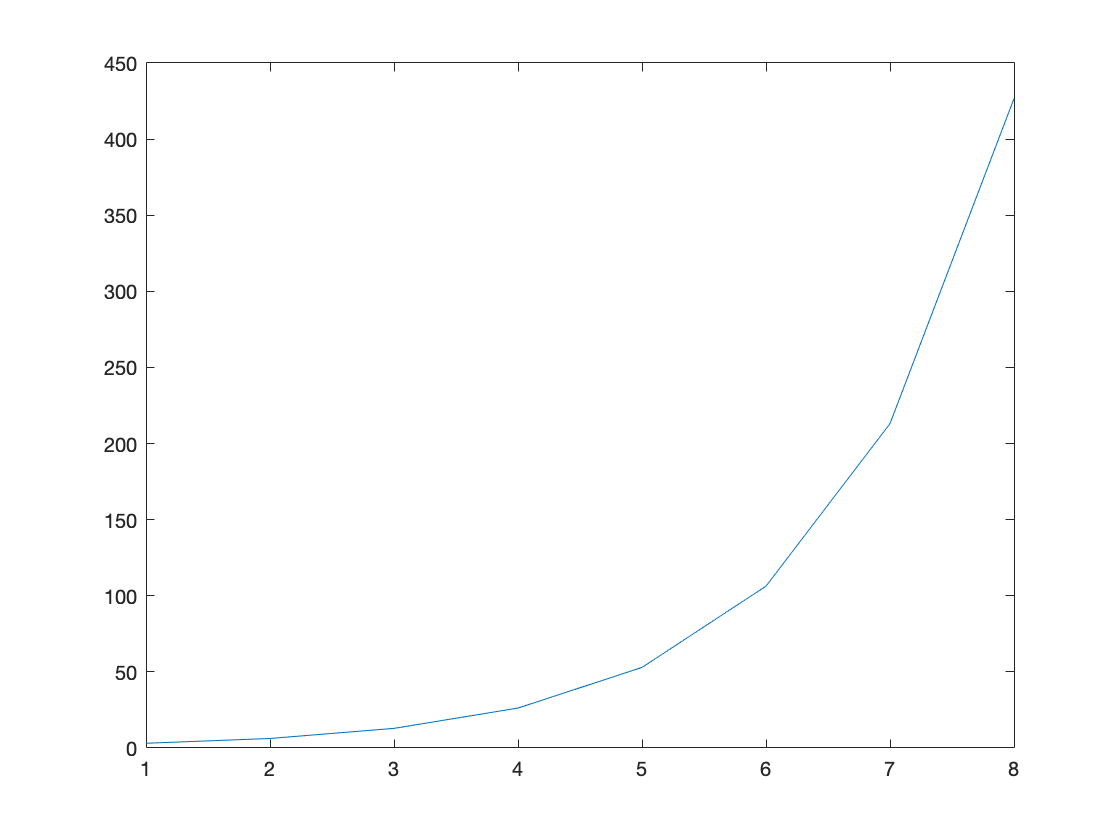

iterations


figure
hold on
plot(log(norms_nm))
xlabel('Iterations')
ylabel('Log Norm')
title('Newtons Method on Arctan(4.0)')
grid on

Newton's method is initialized too far from the functions root in this case, and the algorithm does not converge to a root. At x = 4, the derivative of arctan(x) already approaches 0, but with a slightly positive. An iteration of the algorithm divides by this number, so the new approxmation is x' at which point the tangeant line at x=4 intersect the x-axis. Because the derivative is low, this point is further away from |`x`|=0 than |x|=4. This process repeats by iterations until the approximation of the root is x'', where f(x'') -> 1.571, ie. located on y asymptote, which has a zero derivative, so Newton's fails as it cannot have tangeant lines with coincide with the x-axis. 

This divergence is shown on the plot: the error only increases. 

d) In this part re-implement** Newton-Raphson Method** from part c) to find the roots of $f\left(x\right)\;=\;\arctan \left(x\right)$.

Use $x^{\left(0\right)} =1\ldotp 40$ as initial guess.  Comment on your findings. 

Implement your code in the cell below. Did the Newton-Raphson converge to the root of $f\left(x\right)$? What can you conclude?

clear all;

norms_nm = [];
iterations = 0;

eps = 10^-5;
x0 = 1.3917;

dF = @(x) 1/(x^2+1);

while true
    %evaluate function and its derivative at x0
    Fx0 = atan(x0);
    dFx0 = dF(x0);
    
    %Newtons method
    x = x0 - Fx0 / dFx0;
    
    %check convergence
    root_convergence = norm(x-x0, 'fro');
    norms_nm(iterations+1) = root_convergence;
    
    x0 = x;
    
    if Fx0 == 0
        disp('Exact solution!')
        break
    end
    
    if dFx0 == 0
        %when derivative is 0, Newton's method fails
        disp('Line tangent at x0 does not intersect x-axis. Approximation not possible')
        break
    end
    
    iterations = iterations + 1;
    
    %Check convergence
    if root_convergence < eps || iterations > 100
        break
    end
    
end

disp("Newton's Method result for root of artan(x)")

Newton's Method result for root of artan(x)



root = x0

root = 1.4365e-16

root_convergence

root_convergence = 5.9951e-06

iterations

iterations = 14

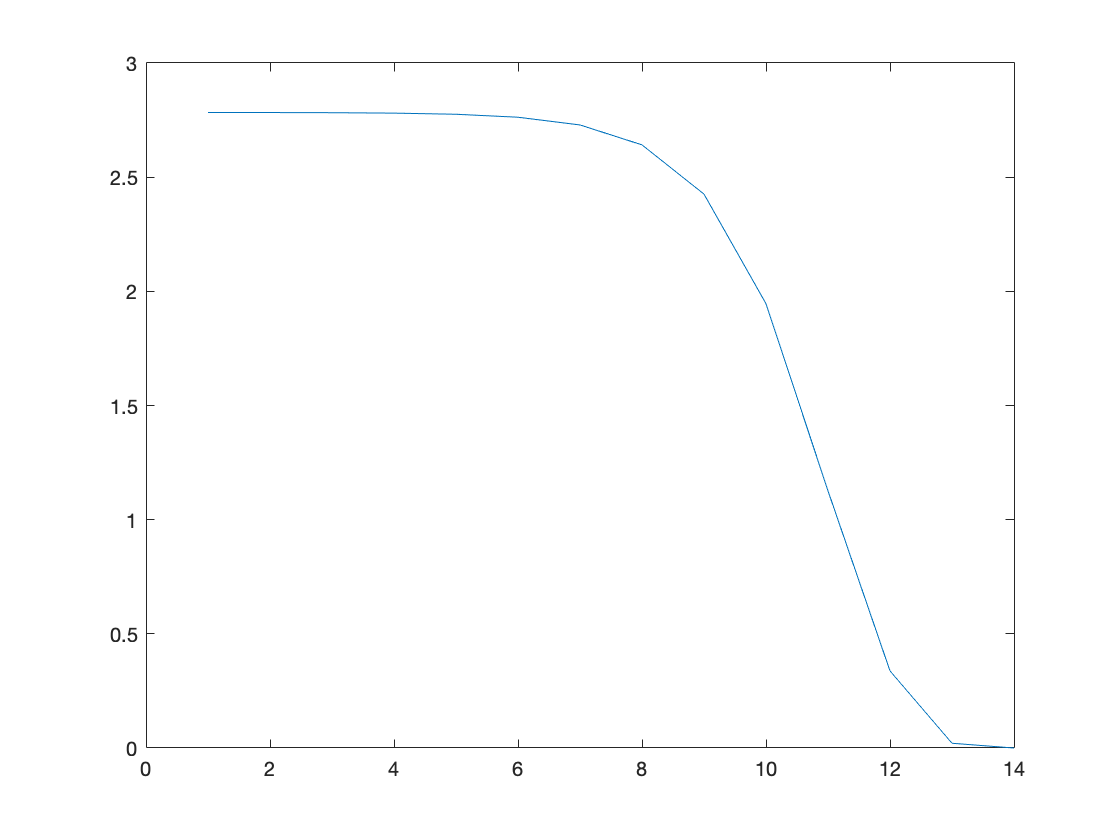



figure
hold on
plot(norms_nm)
xlabel('Iterations')
ylabel('Norm')
title('Newtons Method on Arctan(1.3917)')
grid on



Newton-Raphson's algorithm does not converge to a root for an initial guess of 1.40, but does for an initial guess of 1.39. This is due to the oscillation of the algorithm on arctan(1.39174). 

Between the root 0 and |x| > 1.3975, Newton’s method does not have local convergence as the linear approximation is ineffective on that range. 

Let g =  x1 = x0 - f(x0) / f’(x0) = x0 - (x0^2+1)arctan(x)]  = -x0

since the periodic sequence is (xn) = x0, -x0, x0, -x0 because g is odd. 

2x0 = (x0^2 + 1) arctan(x0)

x0 = 1.39175..

at which point Newton’s method neither converges nor diverges. At |x| > x0, such as x=4,  the algorithm diverges and at |x| < x0, it converges. 

Question 2:  **Nonlinear Equations for N-variables.**

 Newton-Raphson Method can be used to solve the system of nonlinear equations of N-variables, $\left\lbrack x_1 ,\;x_2 ,\;\cdots ,\;x_n \right\rbrack$shown below,


$$f_1 \left(x_1 ,x_2 ,\cdots ,x_N \right)=0$$



$$f_2 \left(x_1 ,x_2 ,\cdots ,x_N \right)=0$$
 


$$\vdots$$



$$f_N \left(x_1 ,x_2 ,\cdots ,x_N \right)=0$$


The above equations can be written as a vector valued function as shown below,


$$\mathit{\mathbf{f}}\left(\mathit{\mathbf{X}}\right)=\left\lbrack \begin{array}{c}
f_1 \left(x_1 ,x_2 ,\cdots ,x_N \right)\\
f_2 \left(x_1 ,x_2 ,\cdots ,x_N \right)\\
\vdots \\
f_N \left(x_1 ,x_2 ,\cdots ,x_N \right)
\end{array}\right\rbrack$$


where $\mathit{\mathbf{X}}=\left\lbrack x_1 ,x_2 ,\cdots ,x_N \right\rbrack$ is the vector containing all the variables.

Following the idea of unidimensional Newton-Rapshson, we start with an initial guess ${\mathit{\mathbf{X}}}^{\left(0\right)}$ and we use this to linearise the function $\mathit{\mathbf{f}}\left(\mathit{\mathbf{X}}\right)$ around${\;\mathit{\mathbf{X}}}^{\left(0\right)}$ 


$$\mathit{\mathbf{f}}\left(\mathit{\mathbf{X}}\right)=\;$$

$$f\left({\mathit{\mathbf{X}}}^{\left(0\right)} \right)+\left(\frac{\partial }{\partial \mathit{\mathbf{X}}}\mathit{\mathbf{f}}\left({\mathit{\mathbf{X}}}^{\left(0\right)} \right)\right)\left(\mathit{\mathbf{X}}-{\mathit{\mathbf{X}}}^{\left(0\right)} \right)$$


Setting the expresson on the left side to zero, we find the approximation of the solution vector. After $k$ iteration the approximation for the solution vector can be written as 


$${\mathit{\mathbf{X}}}^{\left(k+1\right)} =$$

$${\mathit{\mathbf{X}}}^{\left(k\right)} -{\left(\frac{\partial }{\partial \mathit{\mathbf{X}}}\mathit{\mathbf{f}}\left({\mathit{\mathbf{X}}}^{\left(k\right)} \right)\right)}^{-1} \mathit{\mathbf{f}}\left({\mathit{\mathbf{X}}}^{\left(k\right)} \right)$$


where $\mathit{\mathbf{f}}\left({\mathit{\mathbf{X}}}^{\left(k\right)} \right)$ is the vector valued fucntion evaluated at ${\mathit{\mathbf{X}}}^{\left(k\right)}$ and $\left(\frac{\partial }{\partial \mathit{\mathbf{X}}}\mathit{\mathbf{f}}\left({\mathit{\mathbf{X}}}^{\left(k\right)} \right)\right)$ is the jacobian evaluated at ${\mathit{\mathbf{X}}}^{\left(k\right)}$. The structure of the Jacobian is given by,


$$\frac{\partial }{\partial \mathit{\mathbf{X}}}\mathit{\mathbf{f}}\left(\mathit{\mathbf{X}}\right)=\left\lbrack \begin{array}{cccc}
\frac{\partial f_1 }{\partial x_1 } & \frac{\partial f_1 }{\partial x_2 } & \cdots  & \frac{\partial f_1 }{\partial x_n }\\
\frac{\partial f_2 }{\partial x_1 } & \frac{\partial f_2 }{\partial x_2 } & \cdots  & \frac{\partial f_2 }{\partial x_n }\\
\vdots  & \vdots  & \ddots  & \vdots \\
\frac{\partial f_n }{\partial x_1 } & \frac{\partial f_n }{\partial x_2 } & \cdots  & \frac{\partial f_n }{\partial x_n }
\end{array}\right\rbrack$$


The above procedure is repeated untill the following two convergence condtions are simultaneously met,  

- The function value at new guess point is sufficiently small, i.e., ${\left\|\mathit{\mathbf{f}}\left({\mathit{\mathbf{X}}}^{\left(k+1\right)} \right)\right\|}_2 <\epsilon_{\textrm{tolerance}}$

- The difference between the two consecutive solutions is sufficiently small, i.e., ${\left\|{\mathit{\mathbf{X}}}^{\left(k+1\right)} -{\mathit{\mathbf{X}}}^{\left(k\right)} \right\|}_2 <\epsilon_{\textrm{tolerance}}$

Find a solution of the following system of three nonlinear equations using Newton-Raphson method.


$$x_{1\;} x_2 -x_3^2 =1$$



$$x_{1\;} {\;x}_2 \;x_3 -x_1^2 +x_2^2 =2$$



$$e^{x_1 } -e^{x_2 } -x_3 =0$$


Note that this can be expressed as 

$\mathit{\mathbf{f}}\left(\mathit{\mathbf{X}}\right)=\left\lbrack \begin{array}{c}
x_{1\;} x_2 -x_3^2 -1\\
x_{1\;} {\;x}_2 \;x_3 -x_1^2 +x_2^2 -2\\
e^{x_1 } -e^{x_2 } -x_3 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
0\\
0\\
0
\end{array}\right\rbrack$,        where $\mathit{\mathbf{X}}={\left\lbrack \begin{array}{ccc}
x_1  & x_2  & x_3 
\end{array}\right\rbrack }^T$

a) Write a MATLAB function named *evaluateEquations(x)*, that evaluates the above equation at a given input vector. 

Use the framework of the function provided in the Appendix. 

b) Write a MATLAB function named *evaluateJacobian()*, that evaluates the Jacobian of the above equations. 

Use the framework of the function provided in the Appendix. 

c) Implement the Newton-Raphson method, use the function named *NewtonRaphson() *to write the code for this. Use initial guess, $X^{\left(0\right)} ={\left\lbrack \begin{array}{ccc}
35 & 0 & 2
\end{array}\right\rbrack }^T$. Plot the 2-Norm of difference between consecutive solutions ${\left\|{\mathit{\mathbf{X}}}^{\left(k+1\right)} -{\mathit{\mathbf{X}}}^{\left(k\right)} \right\|}_2$ for each iteration. 

Xguess = [35 0 2]';
[X,iter,delta] = NewtonRaphson(Xguess,1e-5)

X =     1.6684
    1.4192
    1.1695


iter = 37

delta =   144.3280   72.1284   36.0035   17.7526    8.1330    2.7757    1.0915    1.0258    1.0257    1.0264    1.0271    1.0279    1.0288    1.0297    1.0307    1.0318    1.0329    1.0342    1.0357    1.0373    1.0390    1.0410    1.0433    1.0458    1.0487    1.0519    1.0552    1.0581    1.0590    1.0538    1.0332    0.9766    0.8469    0.5993    0.2631    0.0407    0.0008    0.0000


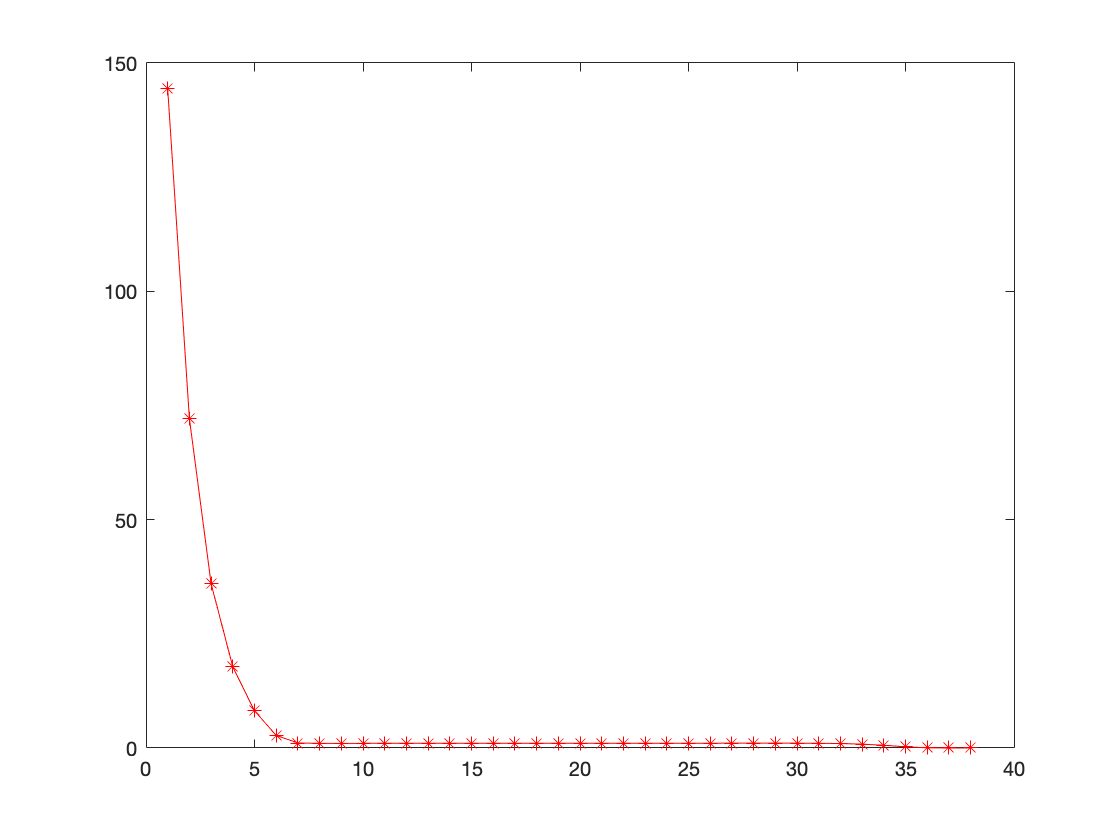


plot(delta,'r-*')

d) Run the part c) using the intial guess  $X^{\left(0\right)} ={\left\lbrack \begin{array}{ccc}
0\ldotp 15 & 0 & 0
\end{array}\right\rbrack }^T$ Explain the differences.** Why is the result  in part (c) different than the result obtained in part (d)? **

Xguess = [0.15 0 0]';
 [X2,iter2,delta2] = NewtonRaphson(Xguess,1e-5)

X2 =    -0.7162
   -1.4935
    0.2640


iter2 = 21

delta2 =    17.1889    8.3482    4.8661    3.6132    1.8378    2.0731    2.2878    1.3819    8.6551   12.0548   10.4440    2.9013    4.1219    2.1439    2.1865    1.7120    0.9431    0.5594    0.1379    0.0090    0.0000    0.0000


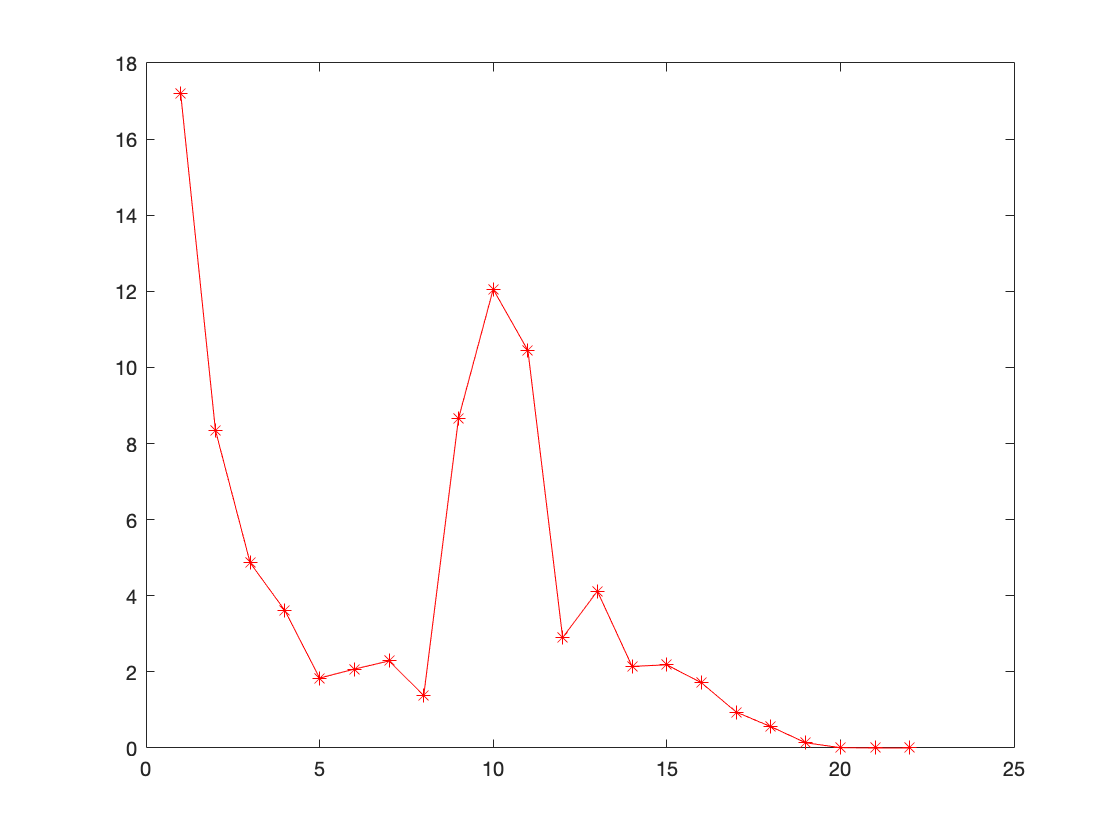

 plot(delta2,'r-*')

The optimization converges to different local minimums, producing different results. This indicates that the initialization matters considerably, as if we are far from the global maxima, we won't get the correct answer, if the function to optimize has a single optima. 

**Note: a way to avoid solving a Jacobian inverse on every iteration**

 X0 = [35 0 2]';

syms x1 x2 x3 F(x1,x2,x3)
F(x1,x2,x3) = [x1*x2-x3^2-1 ; x1*x2*x3-x1^2+x2^2-2 ; exp(x1)-exp(x2)-x3];
J = jacobian(F, [x1,x2,x3]);
invJ = inv(J);
d = invJ*F;

while true
    
    X1 = X0 - d(X0(1), X0(2), X0(3));
    convergence = norm(X1 - X0);
    X0 = X1;
    
    if convergence < 10^05
        break
    end
end

X1

$$X1 = \begin{array}{l} \left(\begin{array}{c} \frac{47503}{\sigma_{1}}-\frac{280\,\left({\mathrm{e}}^{35}-3\right)}{\sigma_{1}}+35\\ \frac{4908\,{\mathrm{e}}^{35}}{\sigma_{1}}-\frac{350}{\sigma_{1}}-\frac{280\,\left({\mathrm{e}}^{35}-3\right)}{\sigma_{1}}\\ \frac{42945\,{\mathrm{e}}^{35}}{\sigma_{1}}-\frac{5\,\left(70\,{\mathrm{e}}^{35}-70\right)}{\sigma_{1}}-\frac{2450\,\left({\mathrm{e}}^{35}-3\right)}{\sigma_{1}}+2 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=280\,{\mathrm{e}}^{35}-2730 \end{array}$$

# Appendix

Question 2) a)

function f  = evaluateEquations(x)
    x1 = x(1);
    x2 = x(2);
    x3 = x(3);
    f = [x1*x2-x3^2-1 ; x1*x2*x3-x1^2+x2^2-2 ; exp(x1)-exp(x2)-x3];
end 

Question 2) b)

function J  = evaluateJacobian(x)
    x1 = x(1);
    x2 = x(2);
    x3 = x(3);
    J = [x2 , x1 , -2*x3 ; x2*x3 - 2*x1 , x1*x3 + 2*x2, x1*x2 ; exp(x1) , -exp(x2), -1];
end

Question 2) c)

function [Xout,iterations, delta]  = NewtonRaphson(Xguess,tolerance)

    delta = [];
    iterations = 0;
    X0 = Xguess;
    
    while(true)
        
        X1 = X0 - inv(evaluateJacobian(X0)) * evaluateEquations(X0);
        
        convergence = norm(X1 - X0);
        delta(iterations+1) = convergence;
        X0 = X1;
        
        if convergence < tolerance
            break
        end
        iterations = iterations + 1;
    end
    Xout = X1;
end